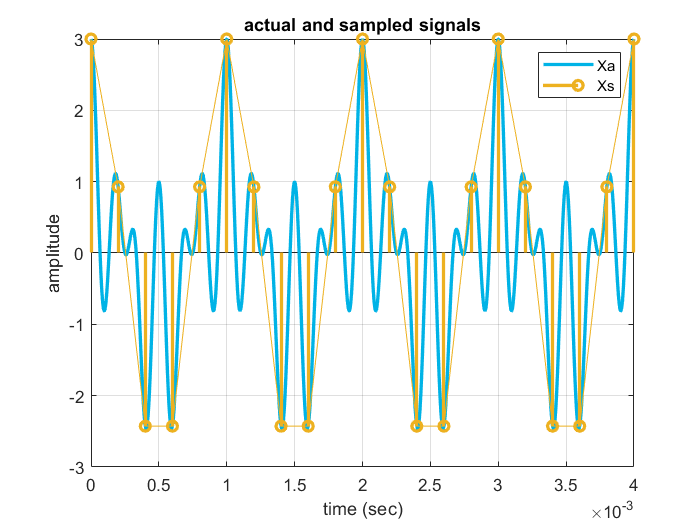


%% part 6 
clc; clear; close all;

f1=1000; f2=4000; f3=6000;
ta=0:0.00000001:0.004; 
ts=0:(1/5000):0.004;

xs=cos(2*pi*f1*ts) + cos(2*pi*f2*ts) + cos(2*pi*f3*ts);
xa=cos(2*pi*f1*ta) + cos(2*pi*f2*ta) + cos(2*pi*f3*ta);

plot(ta,xa,'Color',[0,0.7,0.9],'LineWidth',2),hold on;
stem(ts,xs,'-o','LineWidth',2,'Color',[0.9290 0.6940 0.1250]);
plot(ts,xs,'-o','Color',[0.9290 0.6940 0.1250]);

xlabel("time (sec)");
ylabel("amplitude");
title("actual and sampled signals");
legend ('Xa','Xs');
grid on;

hold off;

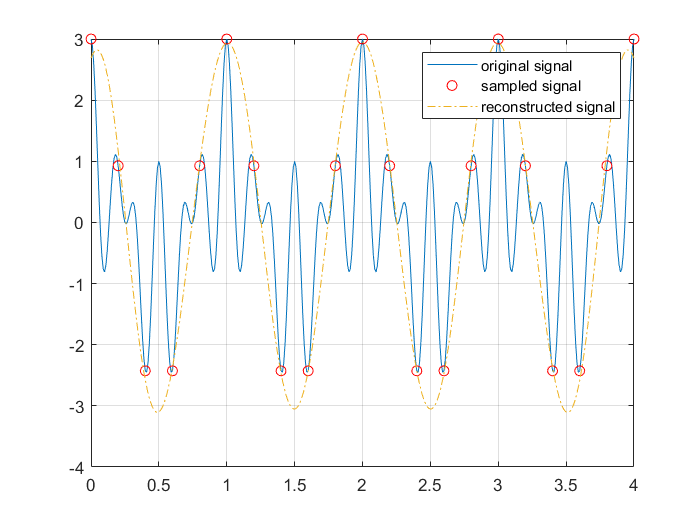

%% part 6 
clc;
clear;
close all;
t3= 0 :0.01: 4 ;
fs_1 = 1 ;
fs_2 = 4 ;
fs_3 = 6 ;
xx = cos(2 * pi * fs_1 * t3 )+cos(2 * pi * fs_2 * t3 )+cos(2 * pi * fs_3 * t3 );
figure (4);
plot(t3 , xx);
t4= 0 :0.2 : 4 ;
figure (4);
hold on ;
xx_2 = cos(2 * pi * fs_1 * t4 )+cos(2 * pi * fs_2 * t4 )+cos(2 * pi * fs_3 * t4 );
plot(t4 , xx_2 , 'or');
yy = zeros (1,length(t3));
for i=1 : length(t4)
    yy = yy + xx_2(i) * (2 * 2 * 0.2) * sinc(2 * 2 * (t3 - t4(i)));    
end
figure (4);
hold on ;
plot (t3 , yy , '-.','Color',[0.9290 0.6940 0.1250]);
legend ('original signal','sampled signal','reconstructed signal')
grid on;

% When reassembling the samplled signal without paying attention to the nyquist frequency
% we would be unable to detect the exact actual signal; however, by considering the nyquist frequency or more
% the actual signal would almost perfectly be detected.


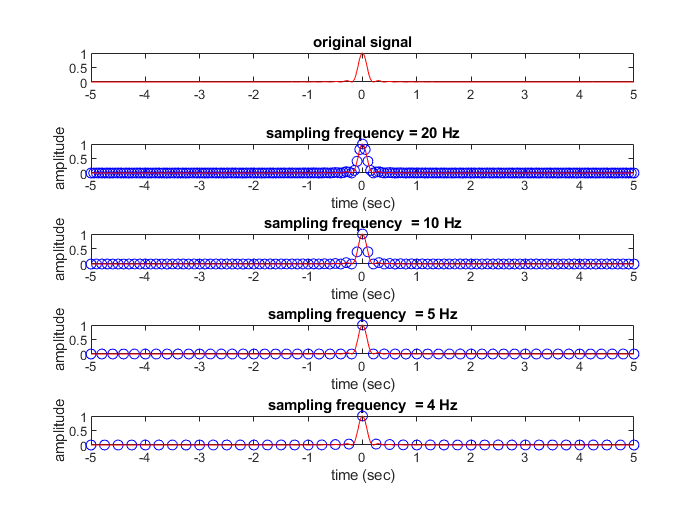


%%part 1-7

clc;clear;close all;
t5 = -5 : 0.01 : 5;
f1=20;
f2=10;
f3=5;
f4=4;
ts1= -5:(1/f1):5;
ts2= -5:(1/f2):5;
ts3= -5:(1/f3):5;
ts4= -5:(1/f4):5;
xa=(sinc(5*t5)).^2;
x1=(sinc(5*ts1)).^2;
x2=(sinc(5*ts2)).^2;
x3=(sinc(5*ts3)).^2;
x4=(sinc(5*ts4)).^2;
figure(5);
subplot(5,1,1);
plot(t5,xa,'r');
title("original signal");
% hold on;
% xx_a = fftshift(fft(xa));
% plot(linspace(-5 ,  5 ,length(xx_a)), abs(xx_a) .^2 ,'b');
subplot(5,1,2);
plot(ts1,x1,'ob');
hold on ;
plot(t5,xa,'r');
% xx_1 = fftshift(fft(x1));
% plot(linspace(-5 ,  5 ,length(xx_1)), abs(xx_1).^2,'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling frequency = 20 Hz");
subplot(5,1,3);
plot(ts2,x2,'ob');
hold on;
plot(t5,xa,'r');
% xx_2 = fftshift(fft(x2));
% plot(linspace(-5 ,  5 ,length(xx_2)), abs(xx_2).^2,'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling frequency  = 10 Hz");
subplot(5,1,4);
plot(ts3 ,x3 ,'ob');
hold on;
plot(t5,xa,'r');
% xx_3 = fftshift(fft(x3));
% plot( linspace(-5 ,  5 ,length(xx_3)), abs(xx_3).^2,'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling frequency  = 5 Hz");
subplot(5,1,5);
plot(ts4,x4,'ob');
hold on;
plot(t5,xa,'r');
% xx_4 = fftshift(fft(x4));
% plot(linspace(-5,  5 ,length(xx_4)), abs(xx_4).^2,'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling frequency  = 4 Hz");

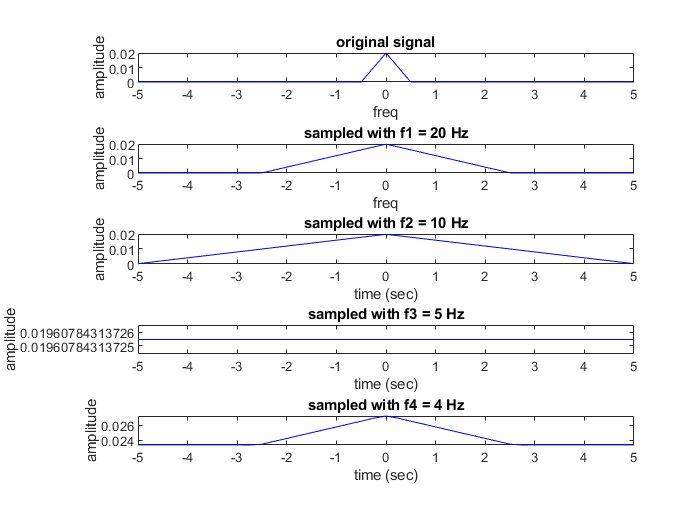

figure (6);
subplot(5,1,1);
la=length(xa);
xx_a = fftshift(fft(xa)/la);
plot(linspace(-5 ,  5 ,length(xx_a)), abs(xx_a)  ,'b');
xlabel("freq");
ylabel("amplitude");
title("original signal");
subplot(5,1,2);
l1=length(x1);
xx_1 = fftshift(fft(x1)/l1);
plot(linspace(-5 ,  5 ,length(xx_1)), abs(xx_1),'b');
xlabel("freq");
ylabel("amplitude");
title("sampled with f1 = 20 Hz");
subplot(5,1,3);
l2=length(x2);
xx_2 = fftshift(fft(x2)/l2);
plot(linspace(-5 ,  5 ,length(xx_2)), abs(xx_2),'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampled with f2 = 10 Hz");
subplot(5,1,4);
l3=length(x3);
xx_3 = fftshift(fft(x3)/l3);
plot( linspace(-5 ,  5 ,length(xx_3)), abs(xx_3),'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampled with f3 = 5 Hz");
subplot(5,1,5);
l4=length(x4);
xx_4 = fftshift(fft(x4)/l4);
plot(linspace(-5,  5 ,length(xx_4)), abs(xx_4),'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampled with f4 = 4 Hz");

% (?) when the sampling frequency raises, the B.W of sampled siganl potentially decreases

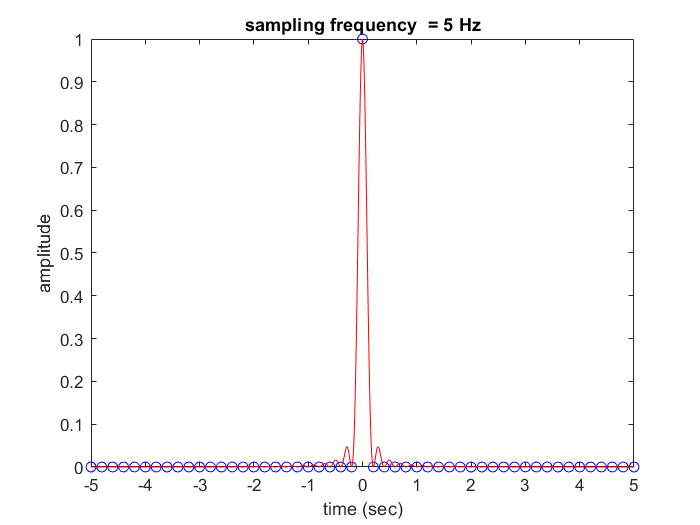


figure;
plot(ts3 ,x3 ,'ob');
hold on;
plot(t5,xa,'r');
% xx_3 = fftshift(fft(x3));
% plot( linspace(-5 ,  5 ,length(xx_3)), abs(xx_3).^2,'b');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling frequency  = 5 Hz");%this sampling rate only take zeros of sinc function

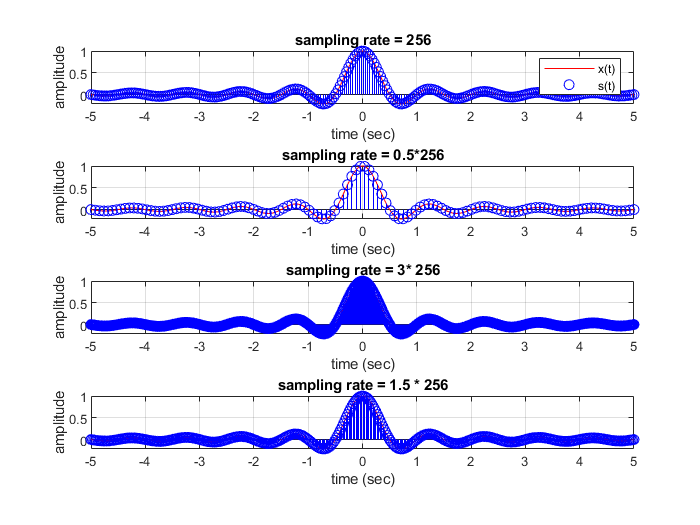


%% part 8 frequency aliasing
% sampled
clc;
clear;
ta = -5 : 0.01 : 5;
xa_8=sinc(2*ta);
figure(7);
subplot(4 , 1 , 1);
plot(ta , xa_8 , 'r' );
hold on ;
t1=linspace(-5 , 5 , 256); 
x1_8=sinc(2*t1);
stem(t1 , x1_8 , 'ob');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling rate = 256");
grid on;
legend('x(t)','s(t)')
subplot(4 , 1 , 2);
plot(ta , xa_8 , 'r' );
hold on ;
t2=linspace(-5 , 5 , 0.5 *256);
x2_8=sinc(2*t2);
stem(t2 , x2_8 , 'ob');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling rate = 0.5*256");
grid on;
subplot(4 , 1 , 3);
plot(ta , xa_8 , 'r' );
hold on ;
t3=linspace(-5 , 5 ,3* 256);
x3_8=sinc(2*t3);
stem(t3 , x3_8 , 'ob');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling rate = 3* 256");
grid on;
subplot(4 , 1 , 4);
plot(ta , xa_8 , 'r' );
hold on ;
t4=linspace(-5 , 5 ,1.5 * 256);
x4_8=sinc(2*t4);
stem(t4 , x4_8 , 'ob');
xlabel("time (sec)");
ylabel("amplitude");
title("sampling rate = 1.5 * 256");
grid on;

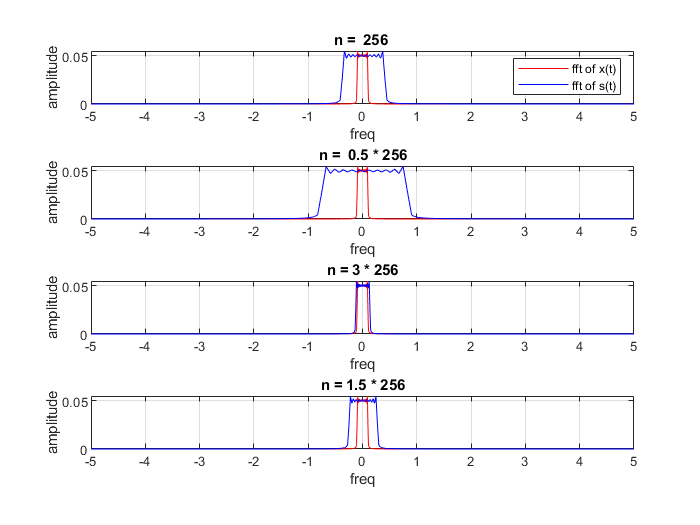

% spectrum
figure(8);
subplot(4,1,1);
la=length(xa_8);
xx_a_8 = fftshift(fft(xa_8)/la); % to normalized
plot(linspace(-5 ,  5 ,length(xx_a_8)), abs(xx_a_8),'r');
hold on ;
l1=length(x1_8);
xx_1_8 = fftshift(fft(x1_8)/l1);
plot(linspace(-5 ,  5 ,length(xx_1_8)), abs(xx_1_8),'b');
xlabel("freq");
ylabel("amplitude");
title("n =  256 ");
legend('fft of x(t)','fft of s(t)')
grid on;
subplot(4,1,2);
la=length(xa_8);
xx_a_8 = fftshift(fft(xa_8)/la);
plot(linspace(-5 ,  5 ,length(xx_a_8)), abs(xx_a_8),'r');
hold on ;
l2=length(x2_8);
xx_2_8 = fftshift(fft(x2_8)/l2);
plot(linspace(-5 ,  5 ,length(xx_2_8)), abs(xx_2_8),'b');
xlabel("freq");
ylabel("amplitude");
title("n =  0.5 * 256");
grid on;
subplot(4,1,3);
la=length(xa_8);
xx_a_8 = fftshift(fft(xa_8)/la);
plot(linspace(-5 ,  5 ,length(xx_a_8)), abs(xx_a_8),'r');
hold on ;
l3=length(x3_8);
xx_3_8 = fftshift(fft(x3_8)/l3);
plot(linspace(-5 ,  5 ,length(xx_3_8)), abs(xx_3_8),'b');
xlabel("freq");
ylabel("amplitude");
title("n = 3 * 256");
grid on;
subplot(4,1,4);
la=length(xa_8);
xx_a_8 = fftshift(fft(xa_8)/la);
plot(linspace(-5 ,  5 ,length(xx_a_8)), abs(xx_a_8),'r');
hold on ;
l4=length(x4_8);
xx_4_8 = fftshift(fft(x4_8)/l4);
plot(linspace(-5 ,  5 ,length(xx_4_8)), abs(xx_4_8),'b');
xlabel("freq");
ylabel("amplitude");
title("n = 1.5 * 256");
grid on;

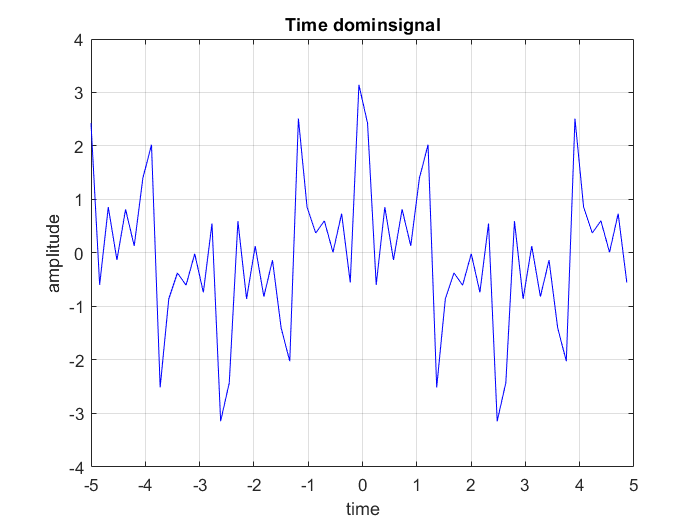

%part 9
clc ;
clear ;
close all;
% 1_9_a
f(1) = 1/16 ;
f(2) = ( pi) / 16 ;
f(3) = ( pi) / 16 ;
f(4) = ( pi) / 16 ;
x = 0;
fs = (2 * pi);
t = -5 : 1/fs : 5 ;
x = cos(fs * (pi/16) * t )+cos(fs *( (5 * pi) / 16) * t )+cos(fs *( (9 * pi) / 16) * t )+cos(fs *( (13* pi) / 16) * t );
%for i=1 : 4
%     x = x  + cos(2 * pi * f(i) * t );
%end

figure(9);
grid on

plot(t,x,'b');
xlabel("time");
ylabel("amplitude");
grid on;
title("Time dominsignal");

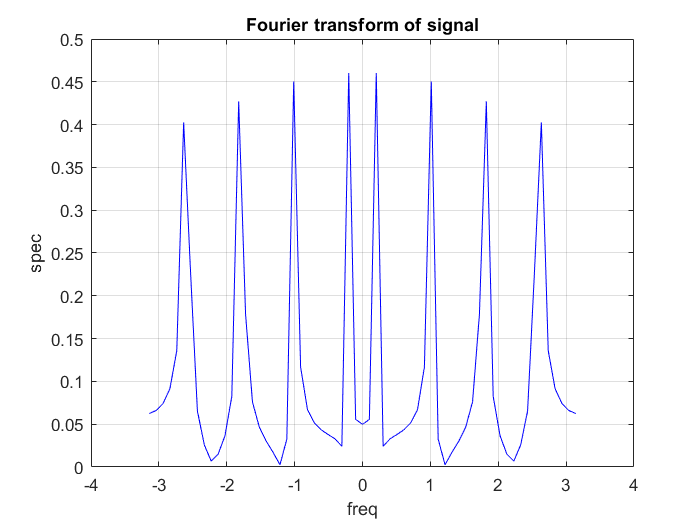

l=length(x);
xx = fftshift(fft(x)/l);
figure(10);
plot(linspace(-l/2 ,  l/2 ,length(xx))* fs/l  , abs(xx),'b');
% plot(linspace(-5 ,  5 ,length(xx)) , abs(xx),'b');
xlabel("freq");
ylabel("spec");
grid on;
title("Fourier transform of signal");

% 1_9_b


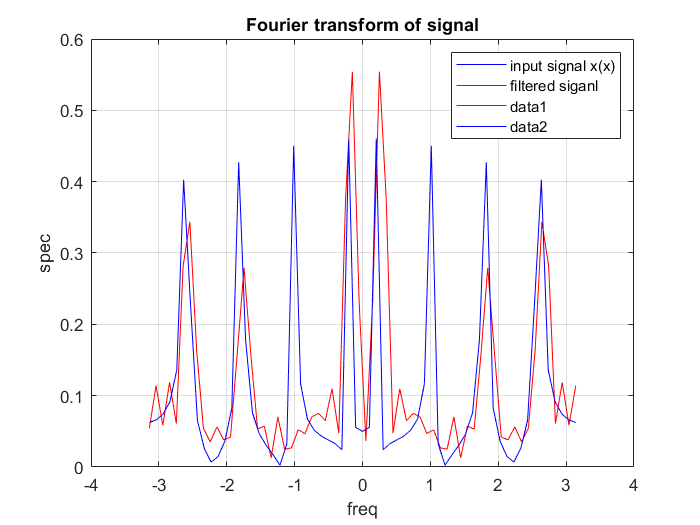


myfilters_analysis  =  xlsread('G:\uni\term9\Az DSP\filters.xls' , 1);
myfilters_synthesis  =  xlsread('G:\uni\term9\Az DSP\filters.xls' , 2);


% 1_9_c
% pu part
%pu =[2 0 1 0.5];
% num1
x1= filter (myfilters_analysis(1 , :),1,x);
x1_d = downsample (x1 , 4);
x2 = 2*x1_d ;
x2_u = upsample (x2 , 4);
x3= filter (myfilters_synthesis(1 , :),1,x2_u);
% o2 = x3(1 : length(t));
% num2
p1= filter (myfilters_analysis(2 , :),1,x);
p1_d = downsample (p1 , 4);
p2 = 0*p1_d ;
p2_u = upsample (p2 , 4);
p3= filter (myfilters_synthesis(2 , :),1,p2_u);
% o2 = p3(1 : length(t));
% num3
q1= filter (myfilters_analysis(3 , :),1,x);
q1_d = downsample (q1 , 4);
q2 = 1*q1_d ;
q2_u = upsample (q2 , 4);
q3= filter (myfilters_synthesis(3 , :),1,q2_u);
% o3 = q3(1 : length(t));
% num4
r1= filter (myfilters_analysis(4 , :),1,x);
r1_d = downsample (r1 , 4);
r2 = 1.5 *r1_d ;
r2_u = upsample (r2 , 4);
r3= filter (myfilters_synthesis(4 , :),1,r2_u);
% o4 = r3(1 : length(t));
% final
out =r3+q3+p3+x3;
% out = o1+o2+o3+o4;
m= length(out);
out_s = fftshift(fft(out)/m);
figure(10);
legend ("input signal x(x)","filtered siganl")
hold on;
plot((linspace(-m/2 ,  m/2 ,length(out_s))* fs/m), abs(out_s),'r');
plot(linspace(-l/2 ,  l/2 ,length(xx))* fs/l  , abs(xx),'b');
grid on

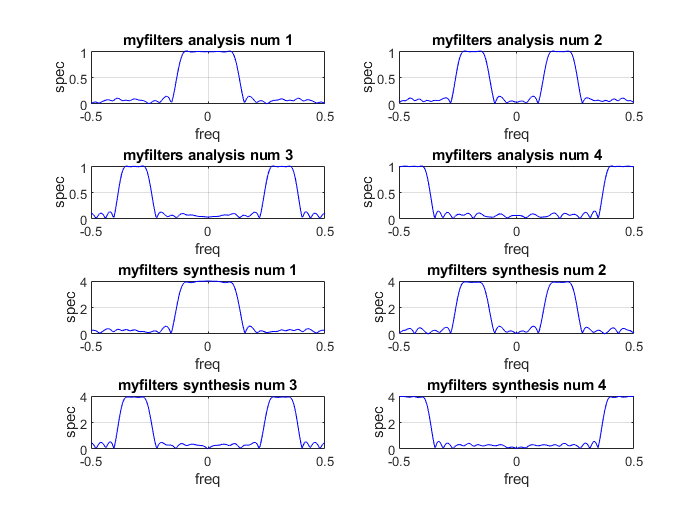

% plot
figure(11);
subplot(4, 2 , 1);
w = linspace(-pi , pi , 256);
y1 = freqz(myfilters_analysis(1 , :),1,w);
plot (w/(2*pi) , (abs((y1))) , 'b');
xlabel("freq");
ylabel("spec");
title("myfilters analysis num 1");grid on;
subplot(4, 2 , 2);
y2 = freqz(myfilters_analysis(2 , :),1,w);
plot (w/(2*pi) ,(abs((y2))) , 'b');
xlabel("freq");
ylabel("spec");
title("myfilters analysis num 2");grid on;
subplot(4, 2 , 3);
y3 = freqz(myfilters_analysis(3 , :),1,w);
plot (w/(2*pi) , (abs((y3))) , 'b');
xlabel("freq");
ylabel("spec");
title("myfilters analysis num 3");grid on;
subplot(4, 2 ,4);
y4 = freqz(myfilters_analysis(4 , :),1,w);
plot (w/(2*pi) , (abs((y4))), 'b');
xlabel("freq");
ylabel("spec");
title("myfilters analysis num 4");grid on;
 
%figure(12);
subplot(4, 2 , 5);
w = linspace(-pi , pi , 256);
s1 = freqz(myfilters_synthesis(1 , :),1,w);
plot (w/(2*pi) , (abs((s1))) , 'b');
xlabel("freq");
ylabel("spec");
title("myfilters synthesis num 1");grid on;
subplot(4, 2 , 6);
s2 = freqz(myfilters_synthesis(2 , :),1,w);
plot (w/(2*pi) , (abs((s2))), 'b');
xlabel("freq");
ylabel("spec");
title("myfilters synthesis num 2");grid on;
subplot(4, 2 , 7);
s3 = freqz(myfilters_synthesis(3 , :),1,w);
plot (w/(2*pi) , (abs((s3))), 'b');
xlabel("freq");
ylabel("spec");
title("myfilters synthesis num 3");grid on;
subplot(4, 2 , 8);
s4 = freqz(myfilters_synthesis(4 , :),1,w);
plot (w/(2*pi) , (abs((s4))) , 'b');
xlabel("freq");
ylabel("spec");
title("myfilters synthesis num 4");grid on;

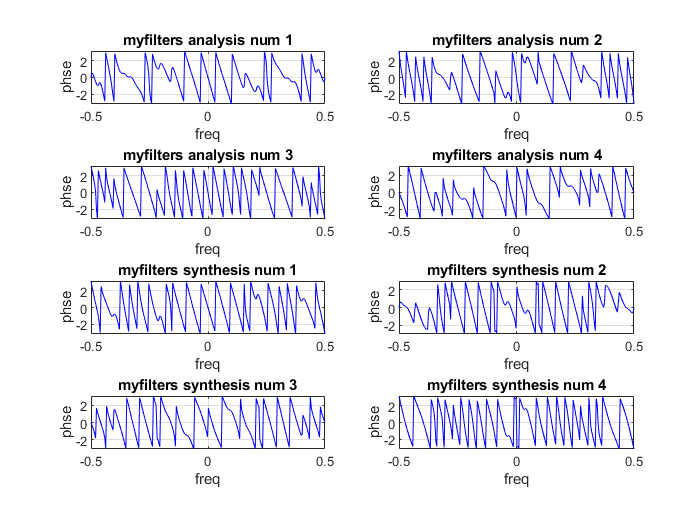

% plot
figure(12);
subplot(4, 2 , 1);
w = linspace(-pi , pi , 256);
y1 = freqz(myfilters_analysis(1 , :),1,w);
plot (w/(2*pi) , (angle((y1))) , 'b');
xlabel("freq");
ylabel("phse");
title("myfilters analysis num 1");
grid on;
subplot(4, 2 , 2);
y2 = freqz(myfilters_analysis(2 , :),1,w);
plot (w/(2*pi) ,(angle((y2))) , 'b');
xlabel("freq");
ylabel("phse");
title("myfilters analysis num 2");
grid on;
subplot(4, 2 , 3);
y3 = freqz(myfilters_analysis(3 , :),1,w);
plot (w/(2*pi) , (angle((y3))) , 'b');
xlabel("freq");
ylabel("phse");
title("myfilters analysis num 3");
grid on;
subplot(4, 2 ,4);
y4 = freqz(myfilters_analysis(4 , :),1,w);
plot (w/(2*pi) , (angle((y4))), 'b');
xlabel("freq");
ylabel("phse");
title("myfilters analysis num 4");
grid on;
 
%figure(12);
subplot(4, 2 , 5);
w = linspace(-pi , pi , 256);
s1 = freqz(myfilters_synthesis(1 , :),1,w);
plot (w/(2*pi) , (angle((s1))) , 'b');
xlabel("freq");
ylabel("phse");
title("myfilters synthesis num 1");
grid on;
subplot(4, 2 , 6);
s2 = freqz(myfilters_synthesis(2 , :),1,w);
plot (w/(2*pi) , (angle((s2))), 'b');
xlabel("freq");
ylabel("phse");
title("myfilters synthesis num 2");
grid on;
subplot(4, 2 , 7);
s3 = freqz(myfilters_synthesis(3 , :),1,w);
plot (w/(2*pi) , (angle((s3))), 'b');
xlabel("freq");
ylabel("phse");
title("myfilters synthesis num 3");
grid on;
subplot(4, 2 , 8);
s4 = freqz(myfilters_synthesis(4 , :),1,w);
plot (w/(2*pi) , (angle((s4))) , 'b');
xlabel("freq");
ylabel("phse");
title("myfilters synthesis num 4");
grid on;